# 配电网 24 小时基态时序交流潮流计算与电压越限诊断

课程名称：《储能优化配置与调度技术》课程设计（随堂演示脚本 01）

## 0. 教学目标与交流潮流数学模型

**教学目标**：

- 掌握 MATPOWER 8.1 标准算例结构体（|mpc.bus|、|mpc.branch|、|mpc.gen|）的数据组织与标幺值转换方法；

- 建立配电网 $T = 24\;\mathrm{h}$ 时序交流潮流（AC Power Flow）循环求解框架；

- 定量诊断配电网在晚高峰重负荷与午间分布式光伏接入下的节点电压越限（安全范围 $[0.95, 1.05]\;\mathrm{p.u.}$）与全天有功网损 $E_{\mathrm{loss}}^{\mathrm{AC}}$，并绘制符合《中国电机工程学报》规范的三维时序电压分布图。

**数学模型（极坐标牛顿-拉夫逊交流潮流方程）**：


$$P_{i,t}^{\mathrm{G}} - P_{i,t}^{\mathrm{L}} = V_{i,t} \sum_{j=1}^{N_{\mathrm{bus}}} V_{j,t} \left( G_{ij}\cos\theta_{ij,t} + B_{ij}\sin\theta_{ij,t} \right), \quad \forall i \in \Omega_{\mathrm{N}}, \forall t \in \mathcal{T}$$



$$Q_{i,t}^{\mathrm{G}} - Q_{i,t}^{\mathrm{L}} = V_{i,t} \sum_{j=1}^{N_{\mathrm{bus}}} V_{j,t} \left( G_{ij}\sin\theta_{ij,t} - B_{ij}\cos\theta_{ij,t} \right), \quad \forall i \in \Omega_{\mathrm{N}}, \forall t \in \mathcal{T}$$


clear; clc; close all;

## 1. 自动挂载算例库与个人学号参数映射

## 1.1 自动检测并挂载算例库路径

若当前 MATLAB 搜索路径中未包含 `case_nongcun.m`，则自动挂载相对路径或弹窗选择 `cases` 文件夹。

if ~exist('case_nongcun.m', 'file')
    rel_case_dir = fullfile(fileparts(mfilename('fullpath')), '..', 'cases');
    if exist(rel_case_dir, 'dir')
        addpath(rel_case_dir);
    elseif exist(fullfile(pwd, 'ESS-Course-Materials', 'cases'), 'dir')
        addpath(fullfile(pwd, 'ESS-Course-Materials', 'cases'));
    else
        case_dir = uigetdir(pwd, '请选择教学资源库中的 cases 文件夹路径');
        if isequal(case_dir, 0)
            error('未选择 cases 文件夹，程序终止。');
        end
        addpath(case_dir);
    end
end

## 1.2 学号哈希映射规则

设学生 9 位学号末两位数字为 $\mathrm{XY}$，十位数字为 $X = \lfloor \mathrm{XY}/10 \rfloor$，个位数字为 $Y = \mathrm{mod}(\mathrm{XY}, 10)$，则个人专属负荷缩放乘子 $\alpha$ 定义为：


$$\alpha = 1 + 0.002 \times \mathrm{XY} \in [1.000, 1.198]$$


Stu_ID  = 242400002;
XY      = mod(Stu_ID, 100);
X_digit = floor(XY / 10);
Y_digit = mod(XY, 10);
alpha   = 1 + 0.002 * XY;

if ismember(Y_digit, [0, 1, 2, 3])
    case_name = 'case_nongcun';
elseif ismember(Y_digit, [4, 5, 6])
    case_name = 'case_chengshi_A';
else
    case_name = 'case_kaifaqu_A';
end

mpc_base = loadcase(case_name);
load('profiles_24h.mat');

if ismember(X_digit, [0, 1, 2])
    pv_buses = [4, 9, 14];
elseif ismember(X_digit, [3, 4, 5])
    pv_buses = [5, 11, 16];
else
    pv_buses = [6, 13, 17];
end
P_pv_peak_MW = 0.8; % 单节点分布式光伏额定装机容量 (MW)

## 2. 逐时段求解 24 小时交流潮流方程

在每个时段 $t \in \{1, 2, \dots, 24\}$，各节点实际有功负荷 $P_{i,t}^{\mathrm{L}}$ 与无功负荷 $Q_{i,t}^{\mathrm{L}}$ 按基准负荷与标幺值曲线缩放：


$$P_{i,t}^{\mathrm{L}} = \alpha \cdot P_{i,0}^{\mathrm{L}} \cdot \tilde{p}_t^{\mathrm{load}}, \quad Q_{i,t}^{\mathrm{L}} = \alpha \cdot Q_{i,0}^{\mathrm{L}} \cdot \tilde{p}_t^{\mathrm{load}}$$


N_bus      = size(mpc_base.bus, 1);
V_bus_24h  = zeros(N_bus, T);
P_loss_24h = zeros(T, 1);
mpopt      = mpoption('verbose', 0, 'out.all', 0);

for t = 1:T
    mpc_t = mpc_base;
    mpc_t.bus(:, 3) = mpc_base.bus(:, 3) * alpha * load_curve_pu(t);
    mpc_t.bus(:, 4) = mpc_base.bus(:, 4) * alpha * load_curve_pu(t);
    mpc_t.bus(pv_buses, 3) = mpc_t.bus(pv_buses, 3) - P_pv_peak_MW * pv_curve_pu(t);

    results = runpf(mpc_t, mpopt);
    V_bus_24h(:, t) = results.bus(:, 8);
    P_loss_24h(t)   = sum(real(get_losses(results)));
end

## 3. 统计越限指标并绘制《中国电机工程学报》规范图表

全天有功电能损耗 $E_{\mathrm{loss}}^{\mathrm{AC}}$ 由全网各支路有功损耗对时间积分求和得到：


$$E_{\mathrm{loss}}^{\mathrm{AC}} = \sum_{t=1}^{T} \sum_{(i,j)\in\Omega_{\mathrm{L}}} P_{ij,t}^{\mathrm{loss}} \Delta t$$


[min_V, linear_idx] = min(V_bus_24h(:));
[min_bus, min_hour] = ind2sub(size(V_bus_24h), linear_idx);

fprintf('算例名称: %s | 学生学号: %d | 负荷系数 alpha: %.3f\n', case_name, Stu_ID, alpha);

算例名称: case_nongcun | 学生学号: 242400002 | 负荷系数 alpha: 1.004


fprintf('全天最低节点电压幅值: %.4f p.u. (发生在节点 %d, 第 %d h)\n', min_V, min_bus, min_hour);

全天最低节点电压幅值: 0.9565 p.u. (发生在节点 13, 第 19 h)


fprintf('全天累计有功网络损耗: %.4f MWh\n', sum(P_loss_24h));

全天累计有功网络损耗: 0.9965 MWh


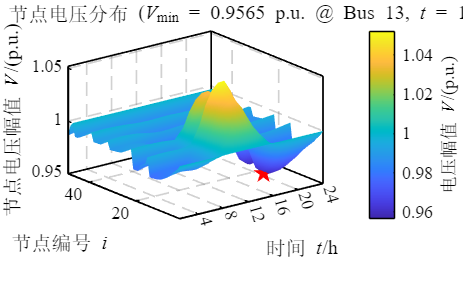


% 绘图规范：强制浅色主题与纯白底色（防止 MATLAB 深色主题下导出黑底图片），中文宋体 + 西文 Times New Roman
fig1 = figure('Name', '配电网24h基态节点电压分布', 'Color', 'w', 'Position', [100, 100, 720, 440]);
if isprop(fig1, 'Theme'), theme(fig1, 'light'); end
surf(1:T, 1:N_bus, V_bus_24h, 'EdgeAlpha', 0.45);
shading interp;
hold on;
plot3(min_hour, min_bus, min_V, 'rp', 'MarkerSize', 11, 'MarkerFaceColor', 'r');
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'ZColor', 'k', ...
    'FontName', 'Times New Roman', 'FontSize', 10.5, 'LineWidth', 1.0, ...
    'Box', 'on', 'TickDir', 'in', 'GridLineStyle', '--', 'GridAlpha', 0.3, 'GridColor', [0.4, 0.4, 0.4]);
xlim([1, T]);
ylim([1, N_bus]);
xticks(0:4:24);
xlabel('\fontname{宋体}时间 \fontname{Times New Roman}{\itt}\rm{/h}', 'FontSize', 12, 'Color', 'k', 'Interpreter', 'tex');
ylabel('\fontname{宋体}节点编号 \fontname{Times New Roman}{\iti}', 'FontSize', 12, 'Color', 'k', 'Interpreter', 'tex');
zlabel('\fontname{宋体}节点电压幅值 \fontname{Times New Roman}{\itV}\rm{/(p.u.)}', 'FontSize', 12, 'Color', 'k', 'Interpreter', 'tex');
title(sprintf('\\fontname{宋体}配电网 24 h 节点电压分布 \\fontname{Times New Roman}({\\itV}_{\\rm{min}} = %.4f p.u. @ Bus %d, {\\itt} = %d h)', ...
    min_V, min_bus, min_hour), 'FontSize', 12, 'FontWeight', 'normal', 'Color', 'k', 'Interpreter', 'tex');
cb = colorbar;
cb.FontName = 'Times New Roman';
cb.FontSize = 10.5;
cb.Color = 'k';
cb.Label.String = '\fontname{宋体}电压幅值 \fontname{Times New Roman}{\itV}\rm{/(p.u.)}';
cb.Label.Interpreter = 'tex';
cb.Label.FontSize = 11;
cb.Label.Color = 'k';
view(-38, 28);
grid on;

% 默认自动导出高质量白底 PNG (600 dpi)、高清 PDF (三维渐变曲面采用 600 dpi 光栅内嵌避免向量化警告) 与 MATLAB 源文件 FIG
exportgraphics(fig1, sprintf('Fig_Task1_Baseline_PF_%d.png', Stu_ID), 'Resolution', 600, 'BackgroundColor', 'white');
exportgraphics(fig1, sprintf('Fig_Task1_Baseline_PF_%d.pdf', Stu_ID), 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', 'white');

savefig(fig1, sprintf('Fig_Task1_Baseline_PF_%d.fig', Stu_ID));